# Simulate Linear Inverted Pendulum Model and Control Bipedal Walking based on Capture Point Dynamics 

Simulate Linear Inverted Pendulum (LIP) model and use capture point dynamics to calculate necessary Zero Moment Point (ZMP) location where base of the next pendulum will be. 

This is based on the work [Bipedal walking control based on Capture Point dynamics](https://ieeexplore.ieee.org/document/6094435) by Englsberger et al.  

## Overview of Control Logic 

First let's get familiar with the jargons. The paper uses capture point to help describe the dynamics of the linear inverted pendulum. Capture point is the point on the floor where the robot (modeled as a LIP) has to step to come to a complete rest [Englsberger]. In other words, if the pendulum's base is changed to capture point, the pendulum will come to a complete rest after certain time. So this is the point where you want to step on (for pendulum) if the goal is to come to a complete rest. 

TODO: 

## Setup

High level parameters for the walking robot are defined here. Based on the desired capture point location at end of each step $\zeta_{\textrm{eos}}$, the controller will find the right location for the ZMP, which is equivalent to the position of the torque-free pendulum base joint. 

close all; 

g = 9.807; 
Ts = 0.005; 
plane_x = 30; 
%original time constant was too small and motion was not smooth enough
motion_time_constant = 0.005; 
contact_damping = 4000; 

zRobot = 0.78;
zModel = 0.68; 
swingHeight = 0.1; 

desiredStepTime = 0.8; 

% create a struct for helper functions to use 
robotParam.Ts = Ts; 
robotParam.zRobot = zRobot; 
robotParam.zModel = zModel; 

Generate desired capture points at end of step $\zeta_{\textrm{eos}}$. These points will be the guideline for how robot walks. Note in this script, the capture point is where the robot will step at the end of step. This could be set with any other off-set. We can set capture point to be some x offset from the robot center of foot.  

${}^b_{\;}T^{\;}_{\textrm{fl}}$: transform from left foot (fl) to center of the robot

${}^b_{\;}T^{\;}_{\textrm{fr}}$: transform from right foot (fr) to center of the robot 

${}^w_{\;}T^{\;}_b$: transform from center of robot to world 

desiredFootTransforms = cell(6, 1); 
desiredCapturePoints = zeros(6, 2);
R = [0 -1 0;0 0 1;-1 0 0]; 
Tb_fl = Transform(-0.12, 0, 0, R);
Tb_fr = Transform( 0.12, 0, 0, R);
Tw_b = Transform(0, 0, 0); 

walkStyle = 1; % 1, 2
if walkStyle == 1 
    % set the capture point so that the robot will rotate some degree every step 
    for idx = 1:length(desiredCapturePoints)
        deltaYaw = deg2rad(15);  
        q = quaternion([0 0 deltaYaw], 'rotvec'); 
        Tb_bp = Transform(0,0,0,q); 
        Tw_b = Tb_bp * Tw_b; 
    
        if mod(idx,2) > 0 
            Tw_fl = Tw_b*Tb_fl;
            desiredFootTransforms{idx} = Tw_fl; 
            desiredCapturePoints(idx,1:2) = [Tw_fl.x; Tw_fl.y]; 
        else 
            Tw_fr = Tw_b*Tb_fr; 
            desiredFootTransforms{idx} = Tw_fr; 
            desiredCapturePoints(idx,1:2) = [Tw_fr.x; Tw_fr.y]; 
        end 
    end 
else
    % Walk in straigt line 
    desiredCapturePoints = [-0.12 0.1;
                             0.12 0.2;
                            -0.12 0.4;
                             0.12 0.5;
                            -0.12 0.5;
                             0.12 0.5]; 
end 

% for now footholds and capture point EOS are same 
desiredfootholds     = desiredCapturePoints; 

### Create the Linear Inverted Pendulum Model

Create a discrete state-space model of the linear inverted pendulum.

w = sqrt(g/zModel); 
w2 = g/zModel; 
A = [0   1 0  0
     w2  0 0  0
     0   0 0  1
     0   0 w2 0]; 
B = [0  0
    -w2 0
     0  0
     0  -w2]; 
C = [1 0 0 0
     0 0 1 0]; 
D = [0 0;0 0]; 

lipm = ss(A,B,C,D); 
lipmD = c2d(lipm, Ts); 

Ad = lipmD.A; 
Bd = lipmD.B;
Cd = lipmD.C;
Dd = lipmD.D;

### Initial State

In this example, the robot will start walking with its center of mass (COM) positioned right above the right foot. 

x0  = 0.12; 
dx0 = 0; 
y0  = 0; 
dy0 = 0; 
state0 = [x0 dx0 y0 dy0]'; 
robotpos0 = [0; 0; zModel]; 

xc = x0; 
yc = y0;
dxc = dx0; 
dyc = dy0; 
cpointx = xc + dxc/w; 
cpointy = yc + dyc/w; 


### Calculate ZMP based on next capture point EOS

This is where Englsberger's control law comes into play. Based on the step time, desired capture point at the end of step (EOS) $\zeta_d$ and the current capture point $\zeta \;$, the ZMP, which is where the base of the pendulum, is found. The desired capture point is basically where you want the robot foot to be. You can place the robot foot to be exactly where capture point is or you could set it so that there is some offset (in this example they are the same). 

The base of the pendulum (ZMP) is determined by the LIPM dynamics so that the robot will move in the direction of the next capture point (where you want the next step to be). The base of pendulum is not coincident (unless the robot is stopped), but you want it to be within the support polygon.

cpdesired = desiredCapturePoints(1,:); %[-0.12 0.1];
px0 = findZMP(w, desiredStepTime, cpdesired(1), cpointx); 
py0 = findZMP(w, desiredStepTime, cpdesired(2), cpointy); 
u0 = [px0 py0]'; 

### Initialize Graphics

Graphics objects help us animate the model. 

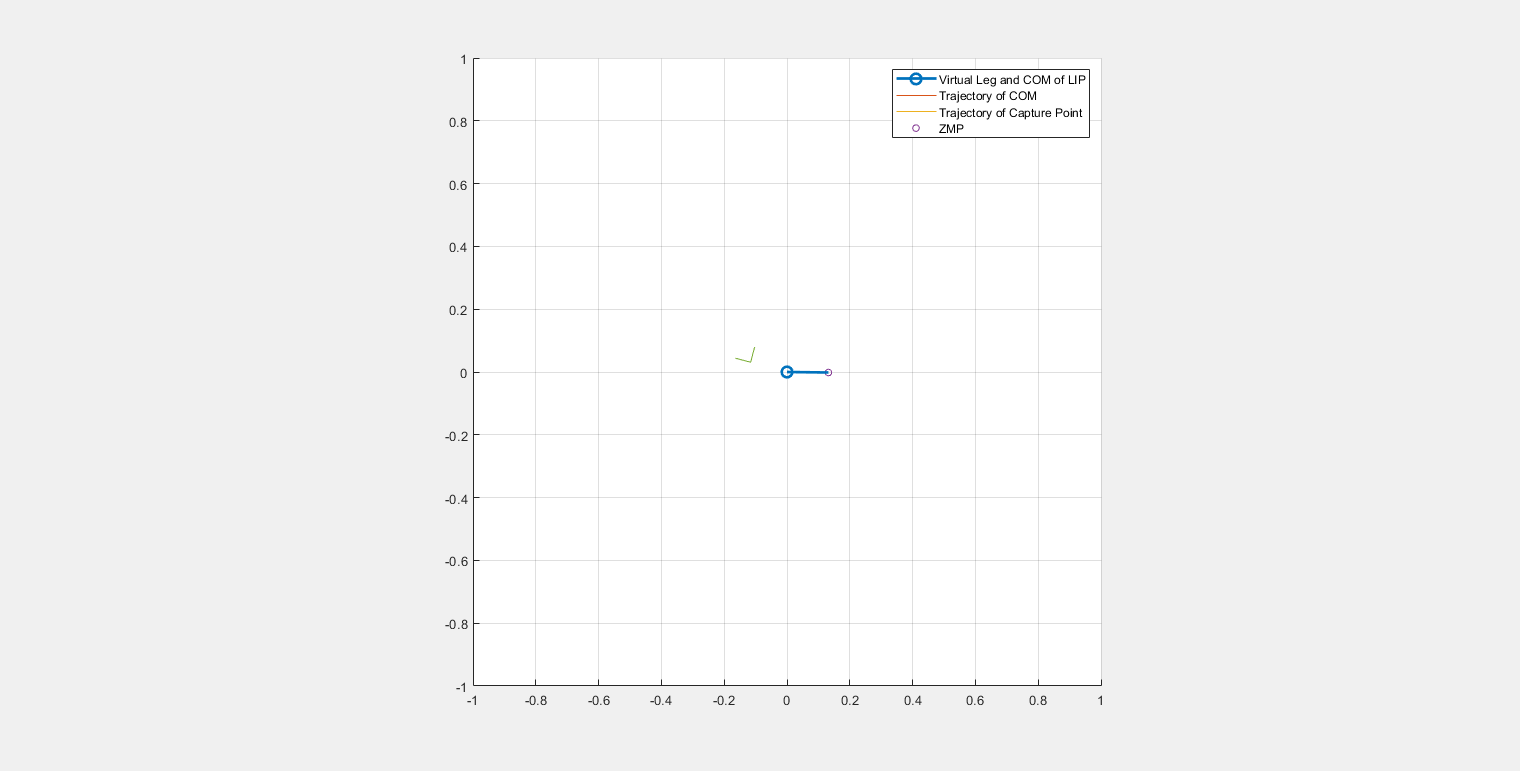

hFig = figure; 
hFig.Visible = 'on'; % for livescript 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0.2 0.2 0.6 0.6]; 
hAx  = axes(hFig); 

% create handles for plots 
hold(hAx, 'on'); 
hLeg  = plot3(hAx,[px0,robotpos0(1)],[py0,robotpos0(2)],[0,robotpos0(3)],...
                '-o','MarkerIndices',2,'LineWidth',2,'MarkerSize',8); % represents com + leg 
hCom = plot3(hAx,robotpos0(1),robotpos0(2),robotpos0(3)); % represents com traj
hCap = plot3(hAx,cpointx,cpointy,0); % represents capture point traj 
hZMP = plot3(hAx,px0,py0,0,'o','MarkerSize',5); % represents ZMPs
% draw foot transform 
transformSize = 0.05; 
[hI, hJ, hK] = desiredFootTransforms{1}.Draw(hAx, [0.466, 0.674, 0.188], transformSize); 

hold(hAx, 'off'); 

grid(hAx, 'on'); 
view(hAx,2)
axis equal 
hAx.XLim = [-1 1]; 
hAx.YLim = [-1 1]; 
legend(hAx, 'Virtual Leg and COM of LIP','Trajectory of COM','Trajectory of Capture Point',...
    'ZMP','Location', 'northeast');   

### Simulate First Stance

During the animation we can see how the capture point behaves as the pendulum moves. After each step time, the capture point does reach the 'desiredcapturepoints'. This was the high level input we set in the beginning which is where the end-of-step capture point $\zeta_{\textrm{eos}}$ will be after each step time. Also this is where the base of the foot is going to be. In the paper, there was an offset between the base of the foot and end-of-step capture point. For simplicity, this example sets them to be the same. 

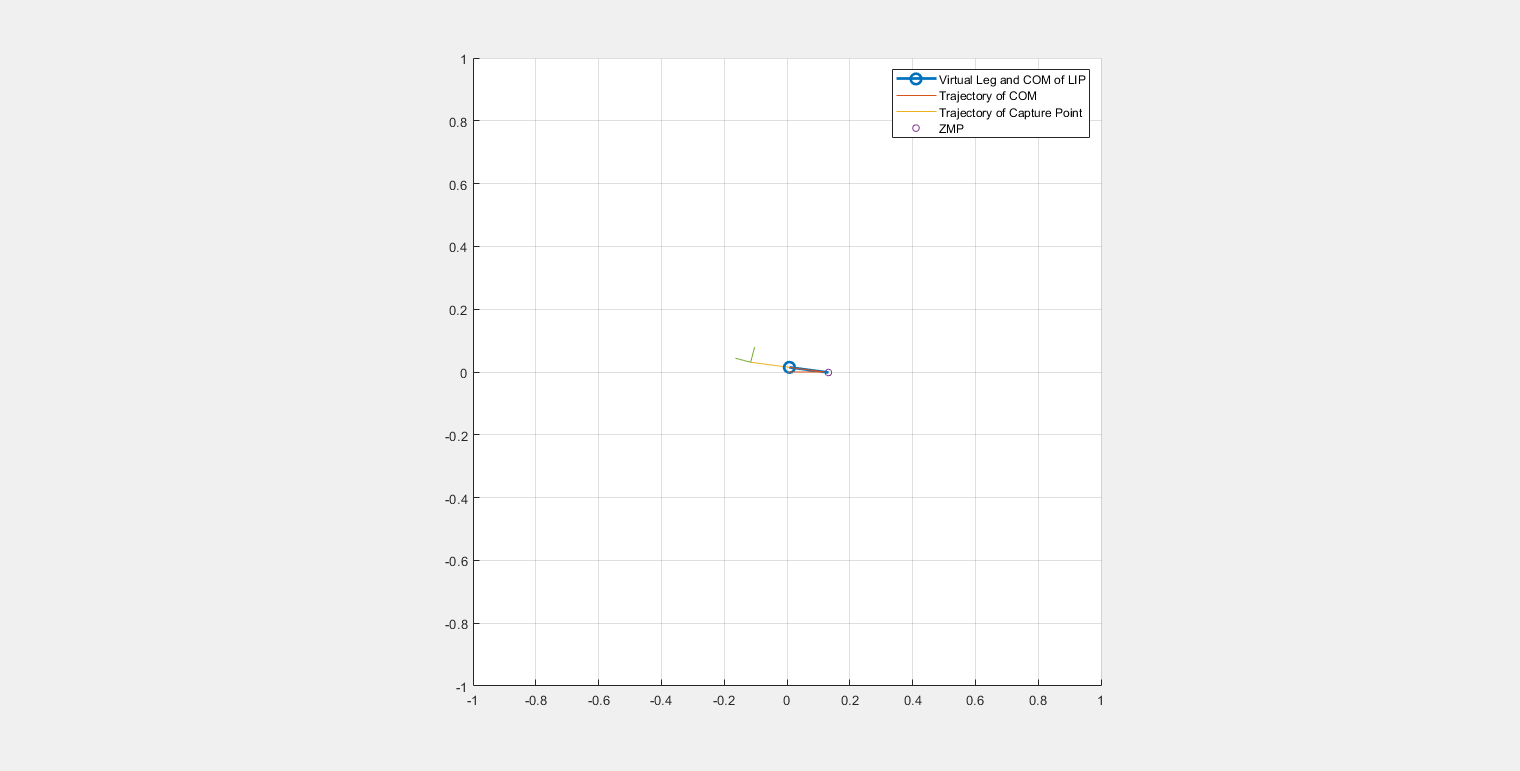

zmppos = [px0; py0; 0]; 
appendLine(hZMP, zmppos);

for idx = 1:round(desiredStepTime/Ts)
    state1 = Ad*state0 + Bd*u0; 
    meas1  = Cd*state1 + Dd*u0; 
    state0 = state1; 
    
    xc = meas1(1); 
    yc = meas1(2);
    dxc = state1(2); 
    dyc = state1(4); 
    cpointx = xc + dxc/w; 
    cpointy = yc + dyc/w; 
    
    cappos = [cpointx; 
              cpointy; 
              0]; 
    bodypos = [xc; 
               yc; 
               zModel]; 
    points = [px0, bodypos(1);
              py0, bodypos(2);
              0,   bodypos(3)]; 
    % update graphics 
    updateLine(hLeg, points);
    appendLine(hCom, bodypos); 
    appendLine(hCap, cappos); 
    pause(0.005); 
end 

### Repeat 

This workflow is much easier to automate the walking process. 

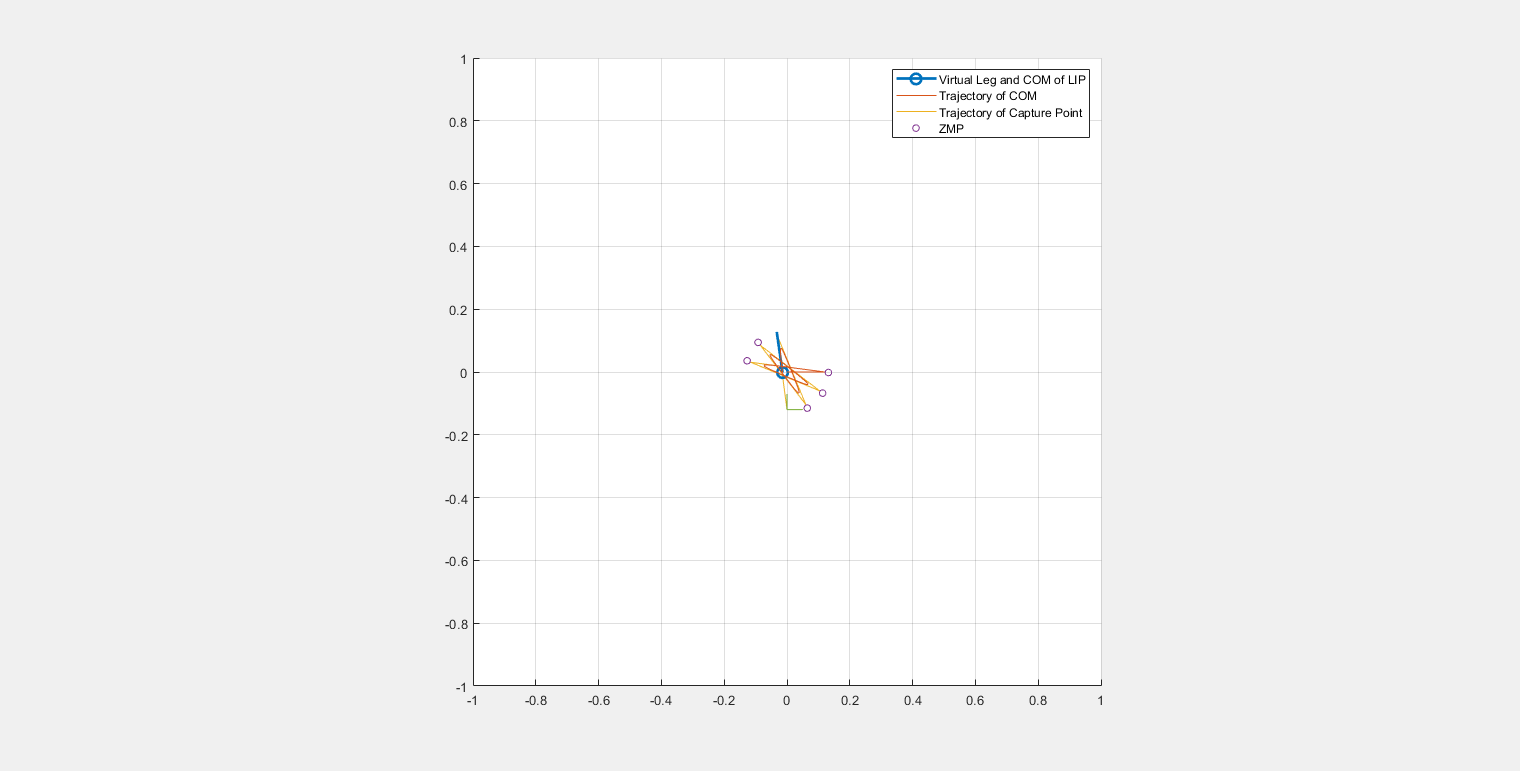

for stepidx = 2:length(desiredCapturePoints)

Calculate ZMP based on next capture point EOS

    cpdesired = desiredCapturePoints(stepidx,:);
    px = findZMP(w, desiredStepTime, cpdesired(1), cpointx); 
    py = findZMP(w, desiredStepTime, cpdesired(2), cpointy); 
    u0 = [px py]'; 
    % update graphics
    desiredFootTransforms{stepidx}.UpdateDraw(hI, hJ, hK, transformSize); 
    appendLine(hZMP, zmppos);

Simulate Stance

    for idx = 1:round(desiredStepTime/Ts)
        state1 = Ad*state0 + Bd*u0; 
        meas1  = Cd*state1 + Dd*u0; 
        state0 = state1; 
        
        xc = meas1(1); 
        yc = meas1(2);
        dxc = state1(2); 
        dyc = state1(4); 
        cpointx = xc + dxc/w; 
        cpointy = yc + dyc/w; 
        
        cappos = [cpointx; 
                  cpointy; 
                  0]; 
        bodypos = [xc; 
                   yc; 
                   zModel]; 
        points = [px, bodypos(1);
                  py, bodypos(2);
                  0,  bodypos(3)]; 
        zmppos = [px; py; 0]; 
        % update graphics 
        updateLine(hLeg, points);
        appendLine(hCom, bodypos); 
        appendLine(hCap, cappos); 
        pause(0.005); 
    end 
end 

Adds points to a graphics line object

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end 

Replaces points in a graphics line object

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end